clear all;
format longg;

problem = input("Problem (1-5): ");

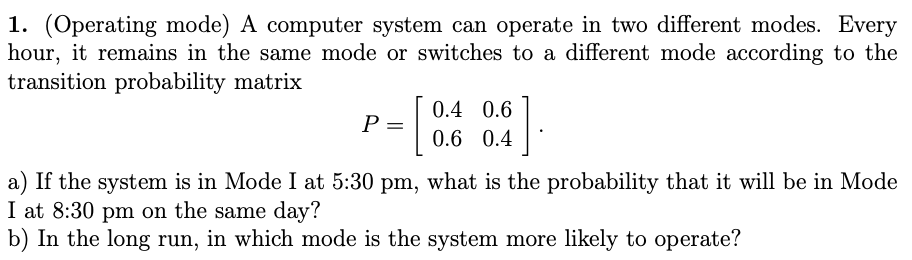

if problem==1
    % Transition matrix
    P = [0.4 0.6; 0.6 0.4]
    
    % a) Probability of being in Mode 1 at 8:30PM (3 hours later)
    P3 = P^3
    prob_mode_1 = P3(1, 1);
    fprintf("a) P(Mode I at 8:30pm | Mode I at 5:30pm) = %g", prob_mode_1);

    % b) Steady-state distribution: [pi1 pi2] * P = [pi1 pi2]
    % Equivalent to: (P' - I) * [pi1; pi2] = 0 with the constraint pi1 + pi2 = 1
    A = [P' - eye(2); 1 1]; % Augment with normalization condition
    b = [0; 0; 1];          % Right-hand side for the system
    steady_state = A\b;

    fprintf("b) P(Mode I Steady-State) = %g\n   P(Mode II Steady-State) = %g", steady_state(1), steady_state(2));
end

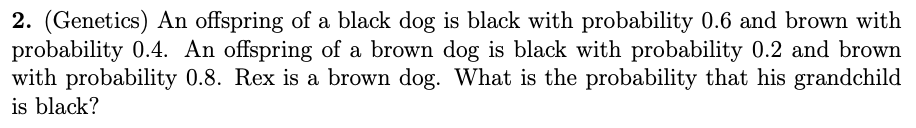

if problem==2
    % Transition matrix
    P = [0.6 0.4; 0.2 0.8]
    
    % Probability of grandchild being black
    P2 = P^2
    prob_black = P2(2, 1);
    
    % Display result
    fprintf('P(Rex''s grandchild is black | Rex is brown) = %g', prob_black);
end

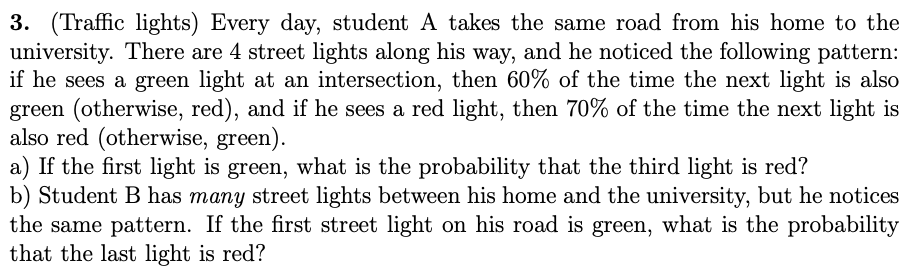

if problem==3
    % Transition matrix
    P = [0.6 0.4; 0.3 0.7]

    % a) Probability that the third light is red if the first one is green
    P2 = P^2
    prob_third_red = P2(1, 2);
    fprintf('a) P(Third light red | First light green) = %g', prob_third_red);

    % b) Steady-state distribution: [pi1 pi2] * P = [pi1 pi2]
    % Equivalent to: (P' - I) * [pi1; pi2] = 0 with the constraint pi1 + pi2 = 1
    A = [P' - eye(2); 1 1]; % Augment with normalization condition
    b = [0; 0; 1];          % Right-hand side for the system
    steady_state = A\b;
    
    fprintf("b) P(Green Light Steady-State) = %g\n   P(Red Light Steady-State) = %g", steady_state(1), steady_state(2));
end

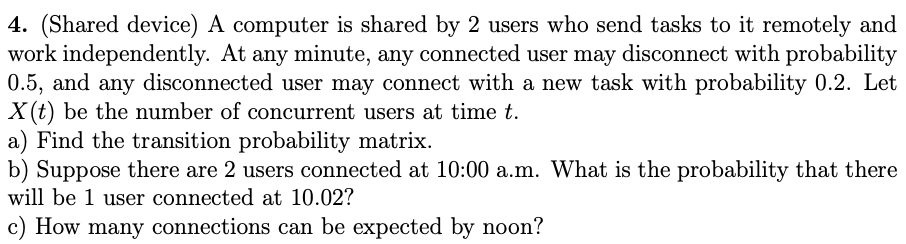

if problem==4
    % a) Transition matrix
    % The number of concurrent users at time t, X(t), can take the values {0, 1, 2}.
    disp('a)')

    Prow1 = binopdf(0:2, 2, 0.2); % from 0 connections is the number of successes in n = 2 trials
    Prow21 = 0.5 * 0.8; % the connected user disconnects and the disconnected doesn't connect
    Prow22 = 0.5 * 0.8 + 0.5 * 0.2; % the connected user remains connected and the
    % disconnected remains disconnected or they swap
    Prow23 = 0.5 * 0.2; % the disconnected user connects and the connected remains connected
    Prow3 = binopdf(2:-1:0, 2, 0.5); % from 2 connections is the number of disconnections in n = 2 trials

    P = [Prow1; Prow21 Prow22 Prow23; Prow3]

    % b) Probability of 1 user connected at 10:02
    disp('b)')
    P2 = P^2
    prob_one_user = P2(3, 2);
    fprintf("P(1 user connected 10:02 | 2 user connected 10:00) = %g", prob_one_user);

    % c)
    disp('c)')
    A = [P' - eye(3); 1 1 1]
    b = [0; 0; 0; 1]
    steady_state = A\b
    
    % Expected number of connections
    expected_connections = steady_state' * (0:2)'
end

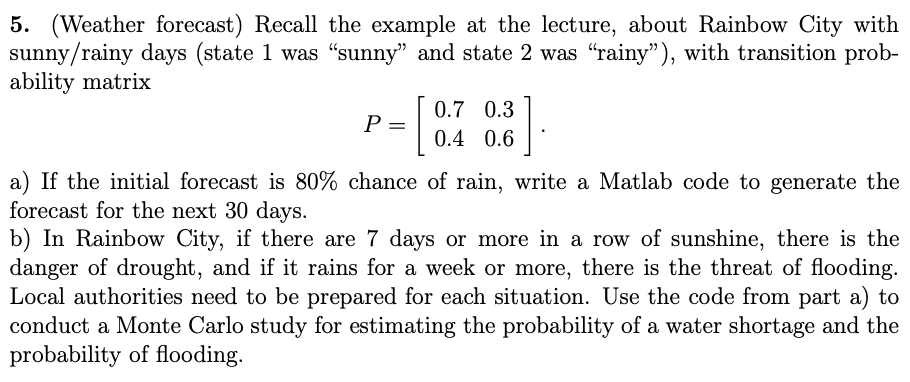

if problem==5
    P0 = [0.2 0.8];
    P = [0.7 0.3; 0.4 0.6];

    % a) Forecast for the next 30 days
    disp('a)')
    forecast_30 = zeros(2, 30);
    forecast_30(:, 1) = P0;
    
    for i=2:30
        forecast_30(:, i) = P' * forecast_30(:, i-1);
    end
    
    % Display the forecast probabilities for 30 days
    disp('Forecast probabilities for the next 30 days (Sunny, Rainy):');
    disp(forecast_30');

    % b) Monte Carlo study for estimating water shortage and flooding
    disp('b)')
    N = input('Nr. of simulations: ');
    water_shortages = zeros(1, N);
    floodings = zeros(1, N);
    for sim=1:N
        rainy_streak = 0;
        sunny_streak = 0;
        for i=1:30
            if rand > forecast_30(1, i)
                if rainy_streak > 0
                    rainy_streak = rainy_streak + 1;
                else
                    if sunny_streak > 7
                        water_shortages(sim) = 1;
                    end
                    sunny_streak = 0;
                    rainy_streak = 1;
                end
            else
                if sunny_streak > 0
                    sunny_streak = sunny_streak + 1;
                else
                    if rainy_streak > 7
                        floodings(sim) = 1;
                    end
                    rainy_streak = 0;
                    sunny_streak = 1;
                end
            end
        end
    end
    fprintf("P(water shortage in the next 30 days): %g", sum(water_shortages) / N);
    fprintf("P(flooding in the next 30 days): %g", sum(floodings) / N);
end

a)


Forecast probabilities for the next 30 days (Sunny, Rainy):


                       0.2                       0.8
                      0.46                      0.54
                     0.538                     0.462
                    0.5614                    0.4386
                   0.56842                   0.43158
                  0.570526                  0.429474
                 0.5711578                 0.4288422
                0.57134734                0.42865266
               0.571404202               0.428595798
              0.5714212606              0.4285787394
             0.57142637818             0.42857362182
            0.571427913454            0.428572086546
           0.5714283740362           0.4285716259638
          0.57142851221086          0.42857148778914
         0.571428553663258         0.428571446336742
         0.571428566098977         0.428571433901023
         0.571428569829693         0.428571430170307
         0.571428570948908         0.428571429051092
         0.571428571284672         0.428571428

b)


P(water shortage in the next 30 days): 0.099957

P(flooding in the next 30 days): 0.015819